# TODO

setup RL agent

mettre en place plusieurs iterations avec changement de spawn initial pour bicycle model

implementer distMin dans fichier Simulink

clear; clc;

### Load environment

open_system('pathPlanningBicycleSimulinkModel.slx')

load exampleMaps.mat

chosenMap = complexMap;
startLoc = randLoc(chosenMap)

startLoc =    49.5000   19.5000


% Orientation aléatoire entre 0 et 2*pi
startOrient = rand*2*pi;
goalLoc = randLoc(chosenMap)

goalLoc =     7.5000   17.5000


### Run model

simulation = sim('pathPlanningBicycleSimulinkModel.slx');

### Visualise everything

#### Define map layout (walls, ...)

map = binaryOccupancyMap(chosenMap)

map =   binaryOccupancyMap with properties:

   mapLayer Properties
              LayerName: 'binaryLayer'
               DataType: 'logical'
           DefaultValue: 0
    GridLocationInWorld: [0 0]
      GridOriginInLocal: [0 0]
     LocalOriginInWorld: [0 0]
             Resolution: 1
               GridSize: [41 52]
           XLocalLimits: [0 52]
           YLocalLimits: [0 41]
           XWorldLimits: [0 52]
           YWorldLimits: [0 41]


#### Get all robot poses

robotPose = simulation.BicyclePose

robotPose =    49.5000   19.5000    5.0283
   49.5175   19.4424    5.0016
   49.5344   19.3846    4.9963
   49.5538   19.3178    4.9954
   49.5802   19.2270    4.9957
   49.6119   19.1174    4.9991
   49.6323   19.0474    4.9969
   49.6527   18.9775    4.9959
   49.6783   18.8893    4.9963
   49.7084   18.7856    4.9986


#### Print map of movements

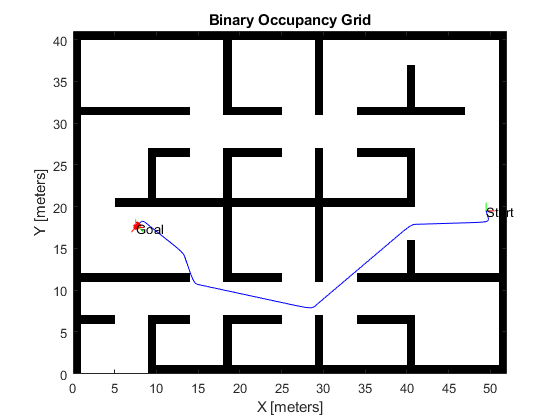

numRobots = size(robotPose, 2) / 3;
thetaIdx = 3;

% Translation
xyz = robotPose;
xyz(:, thetaIdx) = 0;

% Rotation in XYZ euler angles
theta = robotPose(:,thetaIdx);
thetaEuler = zeros(size(robotPose, 1), 3 * size(theta, 2));
thetaEuler(:, end) = theta;

show(map)
hold on;

% Plot Start Location
plotTransforms([startLoc, 0], eul2quat([0, 0, 0]))
text(startLoc(1), startLoc(2), 2, 'Start');

% Plot Goal Location
plotTransforms([goalLoc, 0], eul2quat([0, 0, 0]))
text(goalLoc(1), goalLoc(2), 2, 'Goal');

% Plot Robot's XY locations
plot(robotPose(:, 1), robotPose(:, 2), 'b')

% Plot Robot's pose as it traverses the path
quat = eul2quat(thetaEuler(size(xyz, 1), :), 'xyz');
plotTransforms(xyz(size(xyz, 1),:), quat, 'MeshFilePath',...
    'groundvehicle.stl');

hold off
view([0 90])

function loc = randLoc(map)
% Localisation aléatoire dans la map parmis les endroits libres
    isFree = false;
    sizeMap = size(map);
    while ~isFree
        % inversion de dimensions entre matrice et binaryMap
        loc = [randi([1, sizeMap(2)]) randi([1, sizeMap(1)])];
        transform = changeRepere(loc, sizeMap);
        % vérifie si l'endroit d'apparition est libre
        if map(transform(1), transform(2))==0
            isFree = true;
        end
    end
    % -0.5 sur chaque coordonnée pour ne pas apparaître collé à un mur
    loc = loc-0.5;
end

function transform = changeRepere(loc, sizeMap)
    % si loc vaut [3 2] => checker valeur [hauteur-1 3]
    % si loc vaut [largeur hauteur-2] => checker valeur [3 largeur]
    % si loc vaut [x y] => checker valeur [hauteur-(y-1) x]
    x = loc(1);
    y = loc(2);
    transform = [sizeMap(1)-(y-1) x];
end
